# Binarize Image of Bear Glacier

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

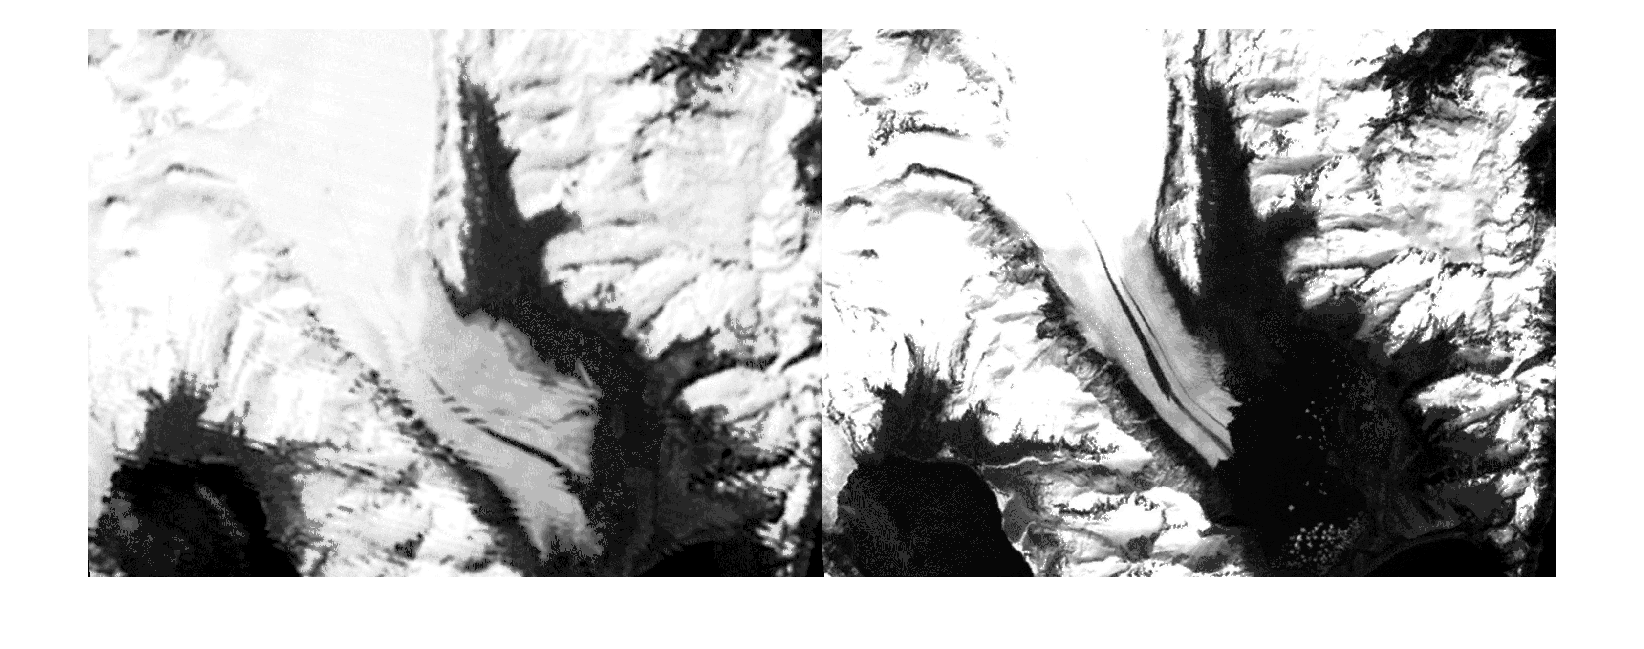

[glacier1980, map1980] = imread("./images/bearGlacier1980.png");
gs1980 = ind2gray(glacier1980, map1980);

[glacier2011, map2011] = imread("./images/bearGlacier2011.png");
gs2011 = ind2gray(glacier2011, map2011);
imshowpair(gs1980, gs2011, "montage")

## Task 1

A more accurate way to estimate glacial melt is to calculate the percent change of ice in the image.


$$\frac{\left(\mathrm{Final}\mathrm{ice}\right)-\left(\mathrm{Initial}\mathrm{ice}\right)}{\mathrm{Initial}\mathrm{ice}}\mathrm{x100}$$


To segment the ice in each image, you can use the `imbinarize` function, which automatically picks threshold for you.

`BW` `=` `imbinarize``(``gs``)``;`

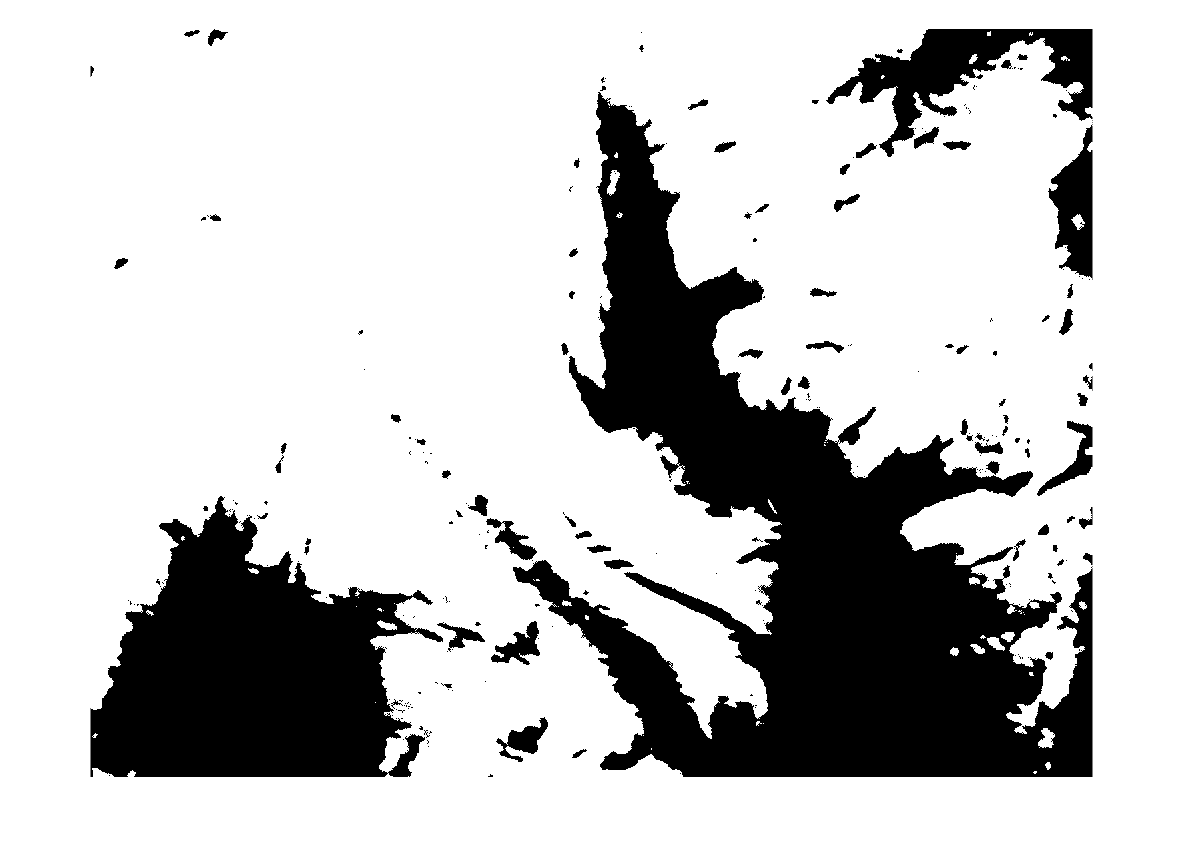

bw1980 = imbinarize(gs1980);
imshow(bw1980)

## Task 2

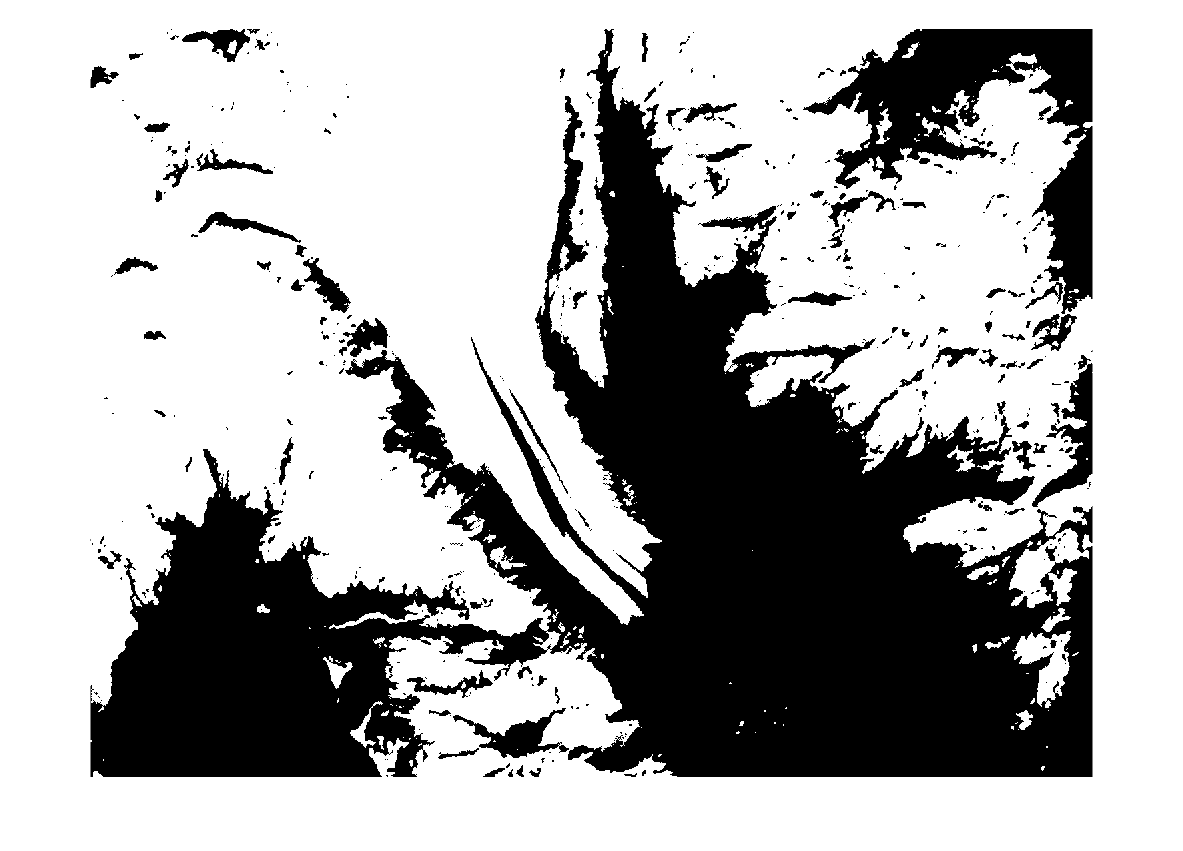

bw2011 = imbinarize(gs2011);
imshow(bw2011)

## Task 3

You can also visualize the difference between two binary images with `imshowpair`.

`imshowpair``(``I1``,``I2``)`

Unlike with grayscale images, there is no variation in the intensities of the green and magenta pixels. Green means a pixel was included in the first image but not the second, and magenta means a pixel was included in the second image but not the first.

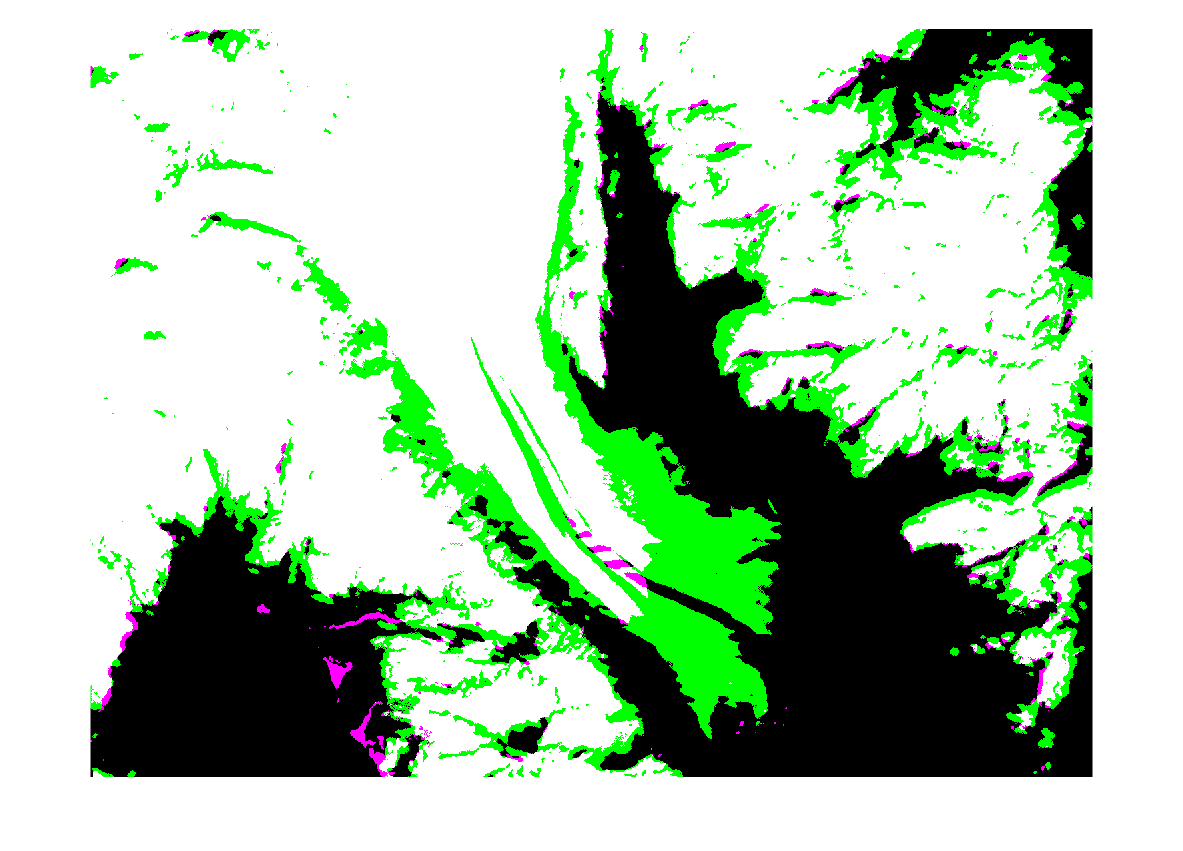

imshowpair(bw1980, bw2011)

## Task 4

To calculate the percent change in ice, first count pixels that have been identified as ice in each image, then calculate the percent change.


$$\frac{\left(\mathrm{Final}\mathrm{ice}\right)-\left(\mathrm{Initial}\mathrm{ice}\right)}{\mathrm{Initial}\mathrm{ice}}\mathrm{x100}$$


iceAmt1980 = nnz(bw1980)

iceAmt1980 = 1173821

iceAmt2011 = nnz(bw2011)

iceAmt2011 = 952798

melt = (iceAmt2011 - iceAmt1980) / iceAmt1980 * 100

melt = -18.8294